# Test Unstable Manifold

## parameters


mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu = 0.0122

## L1 unstable manifold


periodo = 3.36544059

periodo = 3.3654

X0 = [0.798817447531649 0 0 0.365147182312221]

X0 =     0.7988         0         0    0.3651


X0(1,1:2)

ans =     0.7988         0


C1 = jacobiConstant([0.798817447531649	0],[0 0.365147182312221],mu)

C1 = 3.0756

STM = reshape(eye(4),16,[])';
X = [X0 STM]';

k = 40

k = 40

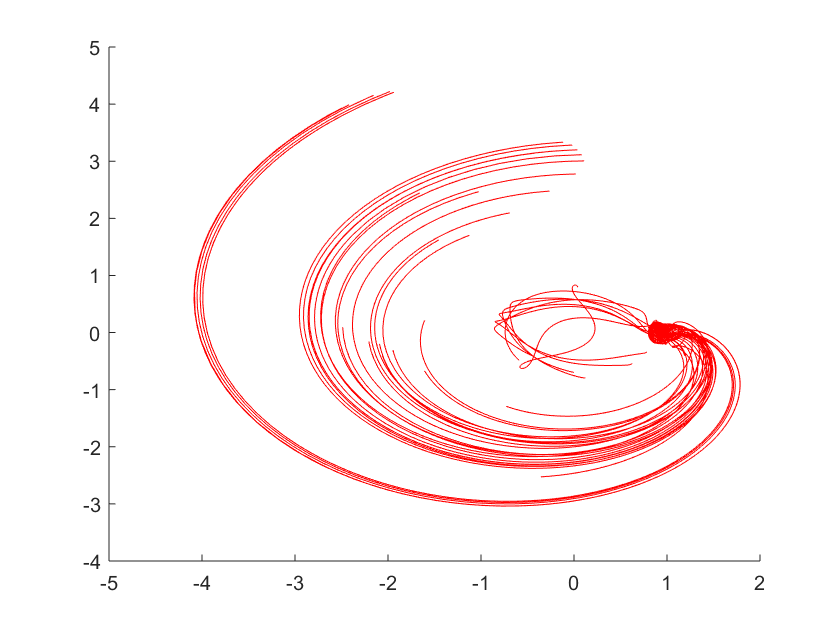

epsilon=1e-6;
X_mainfold = calculateUnStableMainfold(periodo,X,mu,k,epsilon,true);


%% comprobar que manifold esta bien
%epsilon=1e-16;
%X_mainfold = calculateUnStableMainfold(periodo,X,mu,k,epsilon,true);


## L2 unstable manifold

hold on

%tFinalL2 = 4.6065
%[1.2299 0 0 -0,454910328634863]
k = 40;
periodo = 4.2454;
X0 = [1.217882160300000 0 0 -0.420449270532713];
STM = reshape(eye(4),16,[])';
X = [X0 STM]';
%L2 stable manifold
%calculateUnStableMainfold(periodo,X,mu,k,100);
